# Angry Vs. Smiling

### `The goal of today's assignment is to get the best classification rates for the EEG data collected by Sam. We will specifically play around with parameters (types of classifciation algorithms, fe``ature selection, and time windows) to differentiate bbetween angry and smiling data.`

### Load Data

% Clear any variables in the workspace for a fresh start.
clear

% Load data.
load facial_rections_data.mat

%Store the original data in a structure so you can compare and make sure it
%worked.
originalEEG = EEG;

### Gather Data

Find the condition (angry/smile) which has less epochs/trials. This is how many epochs/trials we will keep for each of the conditions. In this case, the angry condition has 57 epochs while the smile condition has 151, so we will keep 57 epochs for both angry and smile.

num_trials_per_cond = min(sum(EEG.epochlabelscat=="A pressed"), sum(EEG.epochlabelscat=="S pressed"));
index_trialstokeep = [find(EEG.epochlabelscat=="A pressed",num_trials_per_cond) find(EEG.epochlabelscat=="S pressed",num_trials_per_cond)];
index_trialstokeep = sort(index_trialstokeep); % This line just puts the trials back in the order they occured.

Next, we will edit the original EEG data to keep only the angry and smile condition data and make sure we did so correctly. 

EEG.data = originalEEG.data(:,:,index_trialstokeep); %Trim the data
EEG.epochlabelscat = originalEEG.epochlabelscat(index_trialstokeep); %Trim the list of labels
EEG.epochlabelscat = removecats(originalEEG.epochlabelscat(index_trialstokeep)); %Remove extra categories
EEG.trials = sum(index_trialstokeep);
%check size of data to make sure it is what we expect it to be.
size(EEG.data);
size(EEG.epochlabelscat);
data = EEG.data;

### Preprocess Data

Now we will preprocess the data given to us. Please note that these data have been prepossed to some extent. 

- a high pass filter at 0.5 Hz to remove drift

- a notch filter from 56 to 64 Hz to remove electrical noise at 60 Hz (this would be 50 Hz, if I were in Europe)

- epoching to chop the data up into 1000 timepoints or 4 seconds sampled at 250 samples per second (250 Hz sampling rate)

Now, we will subtract the mean of each trial from each trial to mean centerize the data for ch1 and ch2.

for channel =1:size(EEG.data,1)
    
    % Trial by trial baseline removal
    EEG.data(channel,:, :) = EEG.data(channel,:, :) - mean(EEG.data(channel,:, :),2);
end

### Split Data into Testing and Training Sets

Since we have a reasonable amount of data, we can split our data into a training and a test set. This helps us avoid overfitting our model to our data, especially as we start tuning parameters and trying out different features. 

We'll use the training set to tweak our model. We can actually do cross-validation or leave out some of the data within the training set to do internal testing.

At the very, very end (after we're settled on a model), then we can apply it to the test set. 

rng(101); % Do this to theoretically get the same split each time (not important for this situation, but important in my lab.)

% Hold out 20% of the data for the testing set.
ttpart = cvpartition(EEG.epochlabelscat,'HoldOut',.20);

% Set up table of data that includes the trial labels
traindata = table(EEG.epochlabelscat(ttpart.training)','VariableNames',{'labels'});

testdata = table(EEG.epochlabelscat(ttpart.test)','VariableNames',{'labels'});

### Feature extraction for selected trials

First, we'll want to set a few paramters. We probably want to include the data from both channels (1 and 2), so we can get the data from the eyebrow and cheek sensors, but it may be interesting to come back to this setting later and look at only one channel.

includedchannels = [1 2]; %channels to included, this will calculate features for each separately

Set the time window to calculate parameters. The data are from -500 to 3496 ms. We might choose to use only a subset of this epoch, especially since it might not make sense to extract information from before the event happened (at 0 ms).

%start and stop in ms. If timepoints don't line up, this will select a slightly later time
timewindowforfeatures = [0 500];

%find the index of the data where this time window values occur.
timewindowepoch_index = (find(EEG.times>=timewindowforfeatures(1),1)):(find(EEG.times>=timewindowforfeatures(2),1));

Now loop through and calculate all of the features based on the settings above and the code below.

Try adding some new features to improve the classifier (you can do this now or circle back to this if you're still trying to understand how the code works). 

Here are some ideas for features to add (you can look these up in the Recognition of Emotion paper from last week or online resources):

- maximum signal (MPV)

- mean of the absolute value of the signal (MAV)

- mmav1 - extension of MAV with weighing factor

- root mean square (RMS) 

- integrated EMG (iEMG)

- simple squared integral (SSI)

- variance of the signal

- bandpower 2- 20 Hz

- bandpower 20 -40 Hz

- bandpower 40 - 56 Hz

- bandpower 64 - 110 hZ

[Mithbavkar, Shraddha Atul, and Milind Shantilal Shah. "Recognition of Emotion Through Facial Expressions Using EMG Signal." 2019 International Conference on Nascent Technologies in Engineering (ICNTE). IEEE, 2019.](https://drive.google.com/file/d/1z2df6YGj-S1I4xbYPOcqUqHkP70LQFSM/view?usp=sharing)

***There are also existing Matlab functions for many of these (or parts of them), so you don't need to code the whole formula from scratch.***

Here is a suggested strategy for adding new features:

- Determine which feature to add (you can see the list above, look at a paper or online, or think of what might be relevant in this kind of data potentially inspired by plotting the data)

- Give your feature a name and add that name to the includedfeatures list below (e.g., 'var')

- Add a new "case" after the "switch" line in the code below. Give it the exact same name: case 'var'

- Calculate the value of the feature for each trial. You can do this in a loop, or you can do it all at once. The end result should be a vector or matrix that has the same number of rows as number of trials in your data (sum(ttpart.training)).

- Store this value in 'fvalues'

% List of all features to include in the data table. Even if others are
% listed below in the case format, they will be ignored unless they are
% listed here.

includedfeatures = {'mpv', 'mmav1', 'absmean','rms','var','bp2t20','bp20t40','bp40t56','bp64t110'};

% You can run this version to just use the raw data, which is not a very good feature, but worth checking out to see how well it does. This probably overfits, so you might want to add downsampling.
%includedfeatures = {'rawdata'};

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Loop through all desired features and put into data table
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Loop through and do this once for the training and once for the test data
% (so they get treated the same way, but are kept separate)
for ttround = 1:2
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Configure things to do training data on the first round and the test
    % data on the second round. You can mostly ignore this and assume it
    % works.
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    if ttround == 1
        %Do training data first
        tempdata = traindata;
        idxt = ttpart.training;
    elseif ttround == 2
        % Do the test data on the second loop
        tempdata = testdata;
        idxt = ttpart.test;
    end
    
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Add features to the data table
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
    % Loop through each channel
    for ch = includedchannels
        
        % To simplify things, we'll assign the raw data to an array. (This
        % is slightly slower and worse for memory, but much easier to read)
        % mydata will be a num timepoints X num trials matrix
        clear mydata;
        mydata = squeeze(EEG.data(ch,timewindowepoch_index,idxt));
        
        
        % Loop through each feature that you want to include by name
        for f = 1:length(includedfeatures)
            
            % We'll use fvalues to temporarily store the vector or matrix
            % of a particular feature of interest. There are other ways to
            % do this, but this setup allows you to loop through options in
            % a consistent way
            fvalues =[]; %clear and initialize fvalues
            
            currentfeature = includedfeatures{f};
            fprintf(strcat('Analysing - ', currentfeature, ' - for channel - ' , num2str(ch),' now. \n'))
            
            % We can use switch and case to find the code for the feature
            % whose name matches currentfeature
            switch currentfeature
                
                case 'mpv'
                    fvalues = max(mydata);
                   
                case 'mmav1'
                    low = prctile(mydata,25,1);
                    high = prctile(mydata,75,1);
                    weightedVals = mydata;
                    weightedVals(weightedVals < low) = weightedVals(weightedVals < low)*.5;
                    weightedVals(weightedVals > high) = weightedVals(weightedVals > high)*.5;
                    fvalues = mean(abs(weightedVals));
                    
                case 'absmean'
                    fvalues = mean(abs(mydata));
                    
                case 'rms'
                    fvalues = rms(mydata);
                    
%                 case 'ssi'
%                     fvalues = jSSI(data);
                    
                case 'var'
                    fvalues = jVAR(mydata);
                          
                case 'bp2t20' %bandpower between 2 and 20 Hz
                    fvalues = bandpower(mydata,EEG.srate,[2 20])';
                    
                case 'bp20t40' %bandpower between 20 and 40 Hz
                    fvalues = bandpower(mydata,EEG.srate,[20 40])';
                    
                case 'bp40t56' %bandpower between 40 and 56 Hz
                    fvalues = bandpower(mydata,EEG.srate,[40 56])';
                    
                case 'bp64t110' %bandpower between 64 and 110 Hz
                    fvalues = bandpower(mydata,EEG.srate,[64 110])';
                    
                case 'rawdata'
                    fvalues = mydata'; %this is just the raw data
                    
                otherwise
                    disp(strcat('unknown feature: ', includedfeatures{f},', skipping....'))
                    
            end
            
            
            % Make sure fvalues is the right shape and put it into the
            % feature table if you can. Otherwise, post a warning and skip
            % it. You can ignore this code.
            if isempty(fvalues)
                % if it's empty, skip all of this
            elseif size(squeeze(fvalues),1) ~= sum(idxt) %if the size is wrong, see if you can fix it
                if size(fvalues,2) == sum(idxt)
                    % If you just need to transpose your data to make it
                    % fit, do so here
                    fvalues = fvalues';
                    eval(['tempdata.FEAT_ch' num2str(ch) '_' includedfeatures{f} ' = fvalues;']);
                else
                    warning(strcat('fvalues does not fit in data table, skipping feature: ', includedfeatures{f},...
                        '. _  Please fix the code to align shapes. Num trials: ',num2str(sum(idxt)),...
                        ' and size fvalues : ',num2str(size(fvalues))))
                end
            else
                
                % Put fvalues into the datatable with appropriate feature name
                % Using the 'eval' function is a really fancy want to make
                % the variable names in the table match the fvalues that
                % you put in. Otherwise, you just need to keep track of
                % which feature you stored in which row, but that requires
                % a lot of organization and can lead to mistakes.
                % Don't worry too much about how this works, just
                % understand that what it is doing is putting the numbers
                % in fvalues into an appropriately named variable in the
                % data
                eval(['tempdata.FEAT_ch' num2str(ch) '_' includedfeatures{f} ' = fvalues;']);
            end
        end
    end
    
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Configure things to do training data on the first round and the test
    % data on the second round. You can mostly ignore this and assume it
    % works.
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    if ttround == 1
        % Put the tempdata into the traindata variable (if this is the
        % first time through)
        traindata = tempdata;
        traindata = splitvars(traindata); %split subvariables into independent variable to not anger the classifier. You really only need this is some of your feature varialbes above are not vectors, but it doesn't hurt to run this line.
        clear tempdata;
    elseif ttround == 2
        % Put the tempdata into the testdata table if it's the second time
        % through
        testdata = tempdata;
        testdata = splitvars(testdata);
        clear tempdata;
    end
    
end

Analysing -mpv - for channel -1 now. 
Analysing -mmav1 - for channel -1 now. 
Analysing -absmean - for channel -1 now. 
Analysing -rms - for channel -1 now. 
Analysing -var - for channel -1 now. 
Analysing -bp2t20 - for channel -1 now. 
Analysing -bp20t40 - for channel -1 now. 
Analysing -bp40t56 - for channel -1 now. 
Analysing -bp64t110 - for channel -1 now. 
Analysing -mpv - for channel -2 now. 
Analysing -mmav1 - for channel -2 now. 
Analysing -absmean - for channel -2 now. 
Analysing -rms - for channel -2 now. 
Analysing -var - for channel -2 now. 
Analysing -bp2t20 - for channel -2 now. 
Analysing -bp20t40 - for channel -2 now. 
Analysing -bp40t56 - for channel -2 now. 
Analysing -bp64t110 - for channel -2 now. 
Analysing -mpv - for channel -1 now. 
Analysing -mmav1 - for channel -1 now. 
Analysing -absmean - for channel -1 now. 
Analysing -rms - for channel -1 now. 
Analysing -var - for channel -1 now. 
Analysing -bp2t20 - for channel -1 now. 
Analysing -bp20t40 - for channel -1

### Understand format of traindata

You can start by viewing the first few rows of the data using the head() function.

head(traindata);

ans = 8×19 table
     labels      FEAT_ch1_mpv    FEAT_ch1_mmav1    FEAT_ch1_absmean    FEAT_ch1_rms    FEAT_ch1_var    FEAT_ch1_bp2t20    FEAT_ch1_bp20t40    FEAT_ch1_bp40t56    FEAT_ch1_bp64t110    FEAT_ch2_mpv    FEAT_ch2_mmav1    FEAT_ch2_absmean    FEAT_ch2_rms    FEAT_ch2_var    FEAT_ch2_bp2t20    FEAT_ch2_bp20t40    FEAT_ch2_bp40t56    FEAT_ch2_bp64t110
    _________    ____________    ______________    ________________    ____________    ____________    _______________    ________________    ________________   

Here are the names of the features:

traindata.Properties.VariableNames';

ans = 19×1 cell array
    {'labels'           }
    {'FEAT_ch1_mpv'     }
    {'FEAT_ch1_mmav1'   }
    {'FEAT_ch1_absmean' }
    {'FEAT_ch1_rms'     }
    {'FEAT_ch1_var'     }
    {'FEAT_ch1_bp2t20'  }
    {'FEAT_ch1_bp20t40' }
    {'FEAT_ch1_bp40t56' }
    {'FEAT_ch1_bp64t110'}
    {'FEAT_ch2_mpv'     }
    {'FEAT_ch2_mmav1'   }
    {'FEAT_ch2_absmean' }
    {'FEAT_ch2_rms'     }
    {'FEAT_ch2_var'     }
    {'FEAT_ch2_bp2t20'  }
    {'FEAT_ch2_bp20t40' }
    {'FEAT_ch2_bp40t56' }
    {'FEAT_ch2_bp64t110'}


Here is some example code, which you can use to explore some other features.

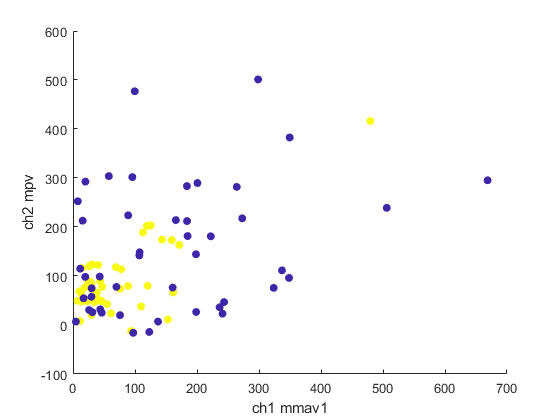

figure; 
scatter(traindata.FEAT_ch1_mmav1,traindata.FEAT_ch2_mpv,36,traindata.labels,'filled');
xlabel('ch1 mmav1'); ylabel('ch2 mpv'); 